Sam Kramer

October 17th, 2023

## KCC Exploration

This live script is for the development of the Kernel Based Cross Correlator function kxcorr() that is going to be used in my research and thesis. This code is going to be in the CPU space and not in the GPU CUDA space that is used within the research. This mainly is going to explore the properties of the function itself and is more of a practical exercise.

%{
    KCC Exploration Notebook

    This live script is for the development of the Kernel Based Cross Correlator 
    function kxcorr() that is going to be used in my research and thesis. This code 
    is going to be in the CPU space and not in the GPU CUDA space that is used within 
    the research. This mainly is going to explore the properties of the function itself 
    and is more of a practical exercise.
   
    Sam Kramer
    October 17th, 2023
%}

% --Setup
    clear; clc; format compact; close all;

% --Signal Parameters
    T = 1;              % Signal Period T (s)
    fs = 10000;         % Sample Rate (Hz)
    t = 0:1/fs:T;
    f = 10*2*pi;        % Frequency (Hz)


## Exploring Gaussian Kernel

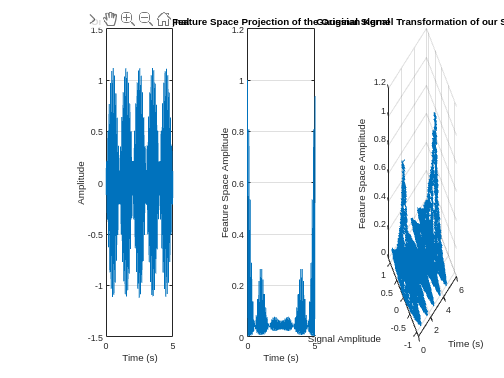

% --Create signal
    amplitude = 0.25;
    envelope = amplitude.* sin(pi*t);
    sig = envelope .* sin(f*t);
    t1 = 0:1/fs:5;
    amplitude = 1;
    envelope = amplitude.* sin(pi*t1);
    signal = envelope .* sin(f*t1);
    noisy_signal = randi(100,1,length(t1))./400 + signal;
    noisy_signal = noisy_signal - mean(noisy_signal);

% --Plot signal
    figure()
    subplot(1,3,1)
    plot(t1,noisy_signal)
        grid on
        hold on
        xlabel('Time (s)')
        title('Original Noisy Signal')
        ylabel('Amplitude')

% --Calling gaussian_kernel
    f_sig = fft(noisy_signal);
    kf = gaussian_kernel(f_sig, f_sig, .4);

% --Plotting gaussian_kernel
    subplot(1,3,2)
    plot(t1, kf)
        hold on
        grid on
        title('Feature Space Projection of the Original Signal')
        xlabel('Time (s)')
        ylabel('Feature Space Amplitude')

    subplot(1,3,3)
    plot3(t1,noisy_signal,kf)
        hold on
        grid on
        title('Gaussian Kernel Transformation of our Signal')
        xlabel('Time (s)')
        ylabel('Signal Amplitude')
        zlabel('Feature Space Amplitude')

                Our Gaussian Kernel that we Just did actually made the smaller parts of our system larger, so we can linearly separate smaller parts of the signal from the larger amplitudes of the signal. The kernel decomposes the signal into dparts based on the amplitudes, so for our application, with weak signals, we can take the gaussian kernel of the signal to separate out the smaller parts of our signal that are perhaps hidden by the comparatively large noise. This also has applications beyond our dataset, becuase we can linearly separate out non-linear data that otherwise would not be linearly separable, this is the "kernel trick" in SVM and data science. Taking the gaussian kernel of the signal with itself is the same as if it were to train the model with the signal as our sample.

## Exploring correlation function

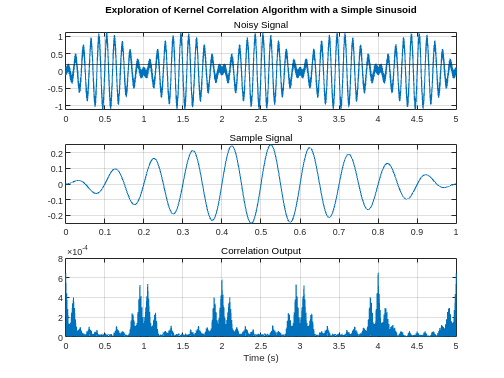

% --Test the correlator function
    corr = kxcorr(noisy_signal, sig, "impulse");
    
% --Plot functions
    figure()
    subplot(3,1,1) 
    plot(t1,noisy_signal)
        yline(0.18)
        grid on
        title('Exploration of Kernel Correlation Algorithm with a Simple Sinusoid')
        subtitle('Noisy Signal')

    subplot(3,1,2)
    plot(t, sig)
        xlim([0, 1])
        grid on
        subtitle('Sample Signal')

    subplot(3,1,3)
    plot(t1,abs(corr))
        grid on
        xlabel('Time (s)')
        subtitle('Correlation Output')

                Our correlation algorithm, actually works, we can see that the spikes that we have are in the locations where the amplitude of the signal precisely matches that of the sample that we checked across our data. This is a function of that gaussian kernel. We decomposed our signal into the different sizes of the amplitude separating out large amplitudes from small amplitude signals, that is shown above in the previus figure. Therefore, we are able to match our datasets amplitudes and find the signal more precisely with larger amplitude signals surrounding it. This bodes well for low SNR signals that we would like to check.

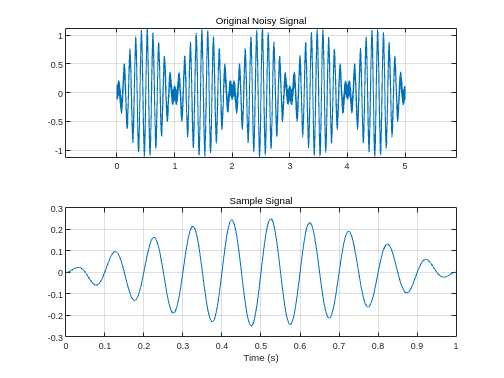

% --Comparison to xcorr() function
    [corr2, lags] = xcorr(noisy_signal, sig);
    lags = lags(1, round(length(lags)/2):end);
    corr2 = corr2(1, round(length(corr2)/2):end)./length(corr2);

% --Plot
    figure()
    subplot(2,1,1)
    plot(t1,noisy_signal)
        grid on
        subtitle('Original Noisy Signal')
        xlim([0 5])
        axis equal

    subplot(2,1,2)
    plot(t, sig)
        xlim([0, 1])
        grid on
        subtitle('Sample Signal')
        hold on
        xlabel('Time (s)')

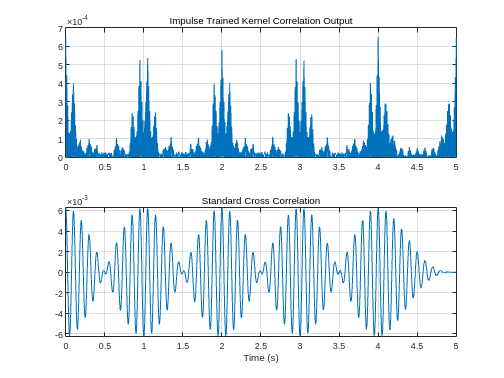


    figure()
    subplot(2,1,1)
        plot(t1,abs(corr))
        grid on
        subtitle('Impulse Trained Kernel Correlation Output')
        xlim([0 5])

    subplot(2,1,2)
    plot(t1, corr2)
        xmax = max(t1);
        xlim([0 xmax])
        grid on
        xlabel('Time (s)')
        subtitle('Standard Cross Correlation')

## Exploring Training Sets

                We are able to change the correlator and train it in different ways by changing the values of the target_fft value within the dataset. This makes the dataset specialized to each problem. We would need to change the training set based on the data. The following code will be on how to define our training sets and use them to benefit us. Because currently, the training sets when they are set to 1, simply return a flat line for the correlator, meaning that we can change it based on the traing set and change the behaviour. 

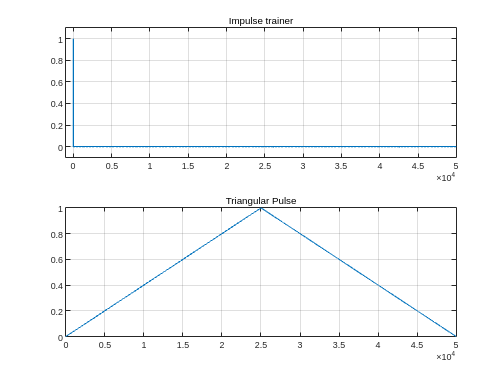

% --Defining the different training sets of the data
    impulse_trainer = zeros(1,size(noisy_signal,2));
    impulse_trainer = [1 impulse_trainer];
    correlation_trainer = corr2;
    x = 0:length(noisy_signal)/2;
    x = [x flip(x)];
    x = x(1:end - 1);
    slope = (1/max(x) .* x);
    b = sind(x)./(x);
    %b = [flip(b) b];
    
% --Plotting our training sets
    figure()
    subplot(2,1,1)
    plot(impulse_trainer, 'LineWidth', 1.5)
        grid on
        subtitle("Impulse trainer")
        xlim([-1000 5*10^4])
        ylim([-0.1 1.1])

    subplot(2,1,2)
    plot(slope)
        grid on
        subtitle("Triangular Pulse")
        xlim([0 5*10^4])

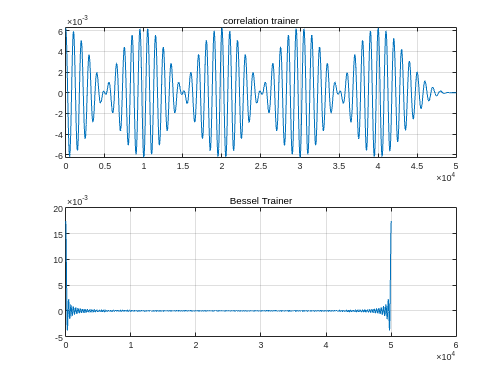

    
    figure()
    subplot(2,1,1)
    plot(correlation_trainer)
        grid on
        subtitle("correlation trainer")
        xlim([0 5*10^4])

    subplot(2,1,2)
    plot(b)
        grid on
        subtitle("Bessel Trainer")

## Reviewing Training Performance

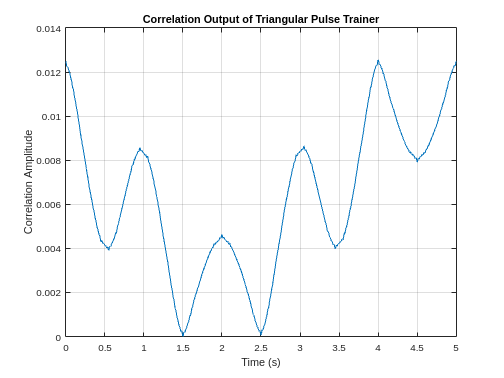

% --Taking the KCC with each training set to see how it responds
    corr_triangular = kxcorr(noisy_signal, sig, "triangle");

    figure() 
    plot(t1, corr_triangular - min(corr_triangular))        % Triangular trainer
        xlabel('Time (s)')
        ylabel('Correlation Amplitude')
        grid on
        title('Correlation Output of Triangular Pulse Trainer');

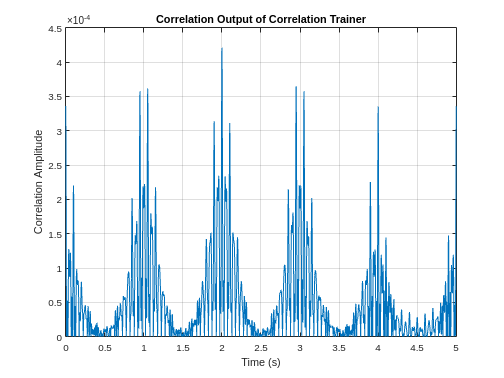


    corr_correlator = kxcorr(noisy_signal, sig, "correlate");

    figure()                                                % Correlation trainer
    plot(t1, abs(corr_correlator))
        hold on
        grid on
        xlabel('Time (s)')
        ylabel('Correlation Amplitude')
        title('Correlation Output of Correlation Trainer')

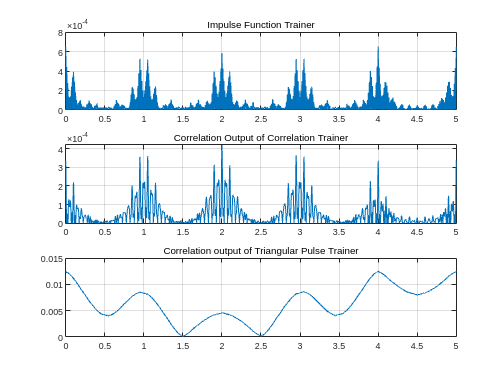


    corr = kxcorr(noisy_signal, sig, "impulse");

    figure()                                                % Impulse trainer
    subplot(3,1,1)
    plot(t1, abs(corr))
        hold on
        grid on
        subtitle('Impulse Function Trainer')

    subplot(3,1,2)
    plot(t1, abs(corr_correlator))
        hold on
        grid on
        subtitle('Correlation Output of Correlation Trainer')

    subplot(3,1,3)
    plot(t1, corr_triangular - min(corr_triangular))
        hold on
        grid on
        subtitle('Correlation output of Triangular Pulse Trainer')

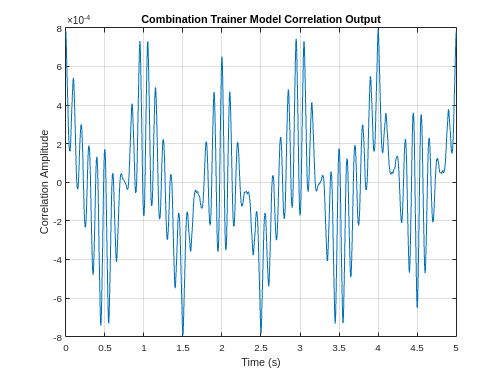


% --Combination of the Triangular pulse trainer and the correlation trainer
    corr3 = kxcorr(noisy_signal, sig, "combo");

    figure()
    plot(t1, corr3)
        grid on
        hold on
        xlabel('Time (s)')
        ylabel('Correlation Amplitude')
        title('Combination Trainer Model Correlation Output')

function output = kxcorr(data, sample, trainer)

        % --Test for column vector
            vec1 = iscolumn(data);
            vec2 = iscolumn(sample);

            if vec1 == 1
                data = data';
            elseif vec2 == 1
                sample = sample';
            end

        % --zero pad sample data to make same length
            if length(sample) < length(data)
                diff = length(data) - length(sample);
                pad = zeros([1, diff]);
                sample = [sample, pad];
            end

        % --Parameters
            lambda = 0.001;
            sigma = 0.2;

        % --Setup
            data_fft = fft(data);

        % --Train Model
            if trainer == "impulse"
                correlator = impulse_train(sample, lambda, sigma);
            elseif trainer == "triangle"
                correlator = triangle_train(sample, lambda, sigma);
            elseif trainer == "correlate"
                correlator = correlate_train(data, sample, lambda, sigma);
            elseif trainer == "bessel"
                correlator = bessel_train(sample, lambda, sigma);
            else
                correlator = train(data, sample, lambda, sigma);
            end

        % --Compute output
            kernel_fft = fft(gaussian_kernel(data_fft, correlator.sample_fft, sigma));
            output = abs(ifft(correlator.h_hat .* kernel_fft));
            output = output - mean(output);

    end

% --Define gaussian_kernel()
    function kf = gaussian_kernel(xf, yf, sigma)
    
        % --Setup Parameters
	        N = numel(xf);

        % --Perform Auto and Cross correlations
	        xx = xf(:)' * xf(:) / N;
	        yy = yf(:)' * yf(:) / N;
	        xy = ifft(xf .* conj(yf));
	    
        % --Find Kernel
            kf = exp(-1 / sigma^2 * (xx + yy - 2 * xy) / N);

    end

% --Define train() [COMBO TRAIN THAT IS USED BY BOTH]
    function correlator = train(data, sample, lambda, sigma)

        % --Early properties of the correlator
            correlator.sigma = sigma; 
            sample_fft = fft(sample);
            correlator.sample_fft = sample_fft;

        % --Calculating correlator 
            kernel = gaussian_kernel(sample_fft, sample_fft, sigma);
            kernel = kernel - mean(kernel);
            k_z = fft(kernel);

        % --Define training objective set (Uncomment sections)

            % --Triangular wave trainer
                x = 0:length(sample)/2;
                x = [x flip(x)];
                x = x(1:end - 1);
                g_hat = 1/max(x) .* x;
                g_hat_1 = abs(fft(g_hat));

            % --Correlation trainer 
                g_hat = xcorr(data, sample);
                g_hat = g_hat(1, round(length(g_hat)/2):end)./length(g_hat);
                g_hat_2 = abs(fft(g_hat));
                g_hat = g_hat_1 .* g_hat_2;          
            
        % --Define h_hat for our system
            % uses the following equation: h_hat = g_hat ./ k(sample)
            correlator.h_hat = g_hat./(k_z + lambda);
    end

% --Define train()
    function correlator = triangle_train(sample, lambda, sigma)

        % --Early properties of the correlator
            correlator.sigma = sigma; 
            sample_fft = fft(sample);
            correlator.sample_fft = sample_fft;

        % --Calculating correlator 
            kernel = gaussian_kernel(sample_fft, sample_fft, sigma);
            kernel = kernel - mean(kernel);
            k_z = fft(kernel);

        % --Define training objective set (Uncomment sections)

            % --Triangular wave trainer
                x = 0:length(sample)/2;
                x = [x flip(x)];
                x = x(1:end - 1);
                g_hat = (1/max(x) .* x);
                g_hat = abs(fft(g_hat));             
            
        % --Define h_hat for our system
            % uses the following equation: h_hat = g_hat ./ k(sample)
            correlator.h_hat = g_hat./(k_z + lambda);
    end

% --Define train()
    function correlator = impulse_train(sample, lambda, sigma)

        % --Early properties of the correlator
            correlator.sigma = sigma; 
            sample_fft = fft(sample);
            correlator.sample_fft = sample_fft;

        % --Calculating correlator 
            kernel = gaussian_kernel(sample_fft, sample_fft, sigma);
            kernel = kernel - mean(kernel);
            k_z = fft(kernel);

        % --Define training objective set (Uncomment sections)

            % --Impulse trainer
                g_hat = ones(1,size(sample,2));             
            
        % --Define h_hat for our system
            % uses the following equation: h_hat = g_hat ./ k(sample)
            correlator.h_hat = g_hat./(k_z + lambda);
    end

% --Define train()
    function correlator = correlate_train(data, sample, lambda, sigma)

        % --Early properties of the correlator
            correlator.sigma = sigma; 
            sample_fft = fft(sample);
            correlator.sample_fft = sample_fft;

        % --Calculating correlator 
            kernel = gaussian_kernel(sample_fft, sample_fft, sigma);
            kernel = kernel - mean(kernel);
            k_z = fft(kernel);

        % --Define training objective set (Uncomment sections)

            % --Correlation trainer 
                g_hat = xcorr(data, sample);
                g_hat = g_hat(1, round(length(g_hat)/2):end)./length(g_hat);
                g_hat = abs(fft(g_hat));          
            
        % --Define h_hat for our system
            % uses the following equation: h_hat = g_hat ./ k(sample)
            correlator.h_hat = g_hat./(k_z + lambda);
    end

% --Define train()
    function correlator = bessel_train(sample, lambda, sigma)

        % --Early properties of the correlator
            correlator.sigma = sigma; 
            sample_fft = fft(sample);
            correlator.sample_fft = sample_fft;

        % --Calculating correlator 
            kernel = gaussian_kernel(sample_fft, sample_fft, sigma);
            kernel = kernel - mean(kernel);
            k_z = fft(kernel);

        % --Define training objective set 
            % --Bessel function training sets
                x = 0:length(sample)/2;
                x = [x flip(x)];
                x = x(1:end - 1);
                b = besselj(0,x);
                g_hat = abs(fft(b));
            
        % --Define h_hat for our system
            % uses the following equation: h_hat = g_hat ./ k(sample)
            correlator.h_hat = g_hat./(k_z + lambda);
    end